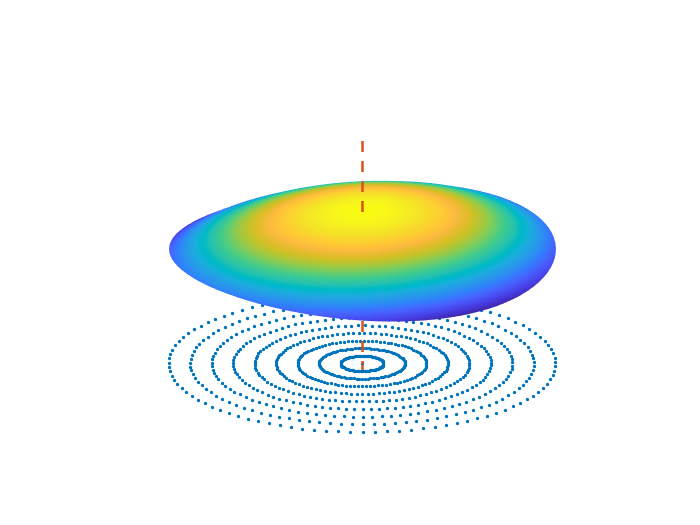

figure;
r = linspace(0,1,10);
theta = linspace(0,2*pi);
xx = r'*cos(theta);
yy = r'*sin(theta);
plot3(xx,yy,zeros(10,100),'.','Color',[0,0.45,0.74]);
hold on;

syms x y;
R = 2;
A = 0.8;
B = 0.7;
surfSym = sqrt(R.^2 - x.^2/A^2 - y.^2/B^2);
surfFunc = matlabFunction(surfSym);
zz = surfFunc(xx,yy);
surf(xx,yy,zz,'EdgeColor','none','FaceColor','interp');

line([0,0],[0,0],[-.1,3],'Color',[0.8500,0.3250,0.0980],'LineStyle','--','LineWidth',1.5);

set(gca,'xtick',[],'xticklabel',[], ...
    'ytick',[],'yticklabel',[], ...
    'ztick',[],'zticklabel',[]);
set(gca,'XColor','white','YColor','white','ZColor','white');

## 等弧长等距

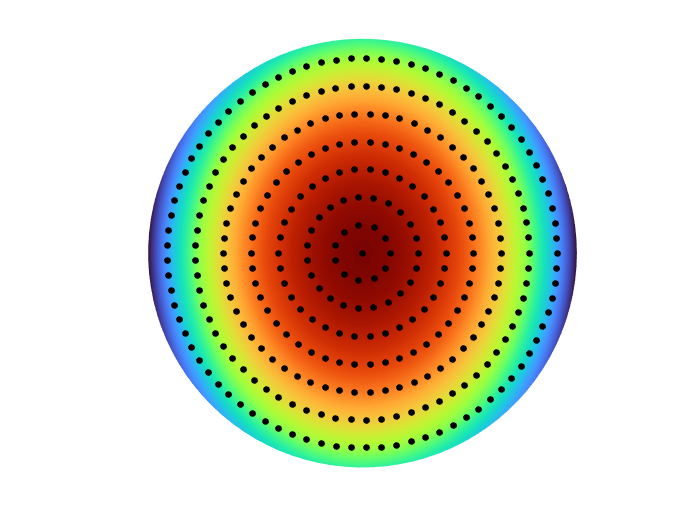

arcLength = 0.077;
r = linspace(0,1,8);
spar = ceil(2*pi*r/arcLength);
xx = [];
yy = [];
for ii = 1:8
    theta = linspace(0,2*pi,spar(ii));
    xx = [xx,r(ii)*cos(theta)];
    yy = [yy,r(ii)*sin(theta)];
end

syms x y;
R = 2;
A = 0.7;
B = 0.85;
surfSym = sqrt(R.^2 - x.^2/A^2 - y.^2/B^2);
surfFunc = matlabFunction(surfSym);

figure;
rr = linspace(0,1.1,10);
ttheta = linspace(0,2*pi);
xxx = rr'*cos(ttheta);
yyy = rr'*sin(ttheta);
surf(xxx,yyy,surfFunc(xxx,yyy),'EdgeColor','none','FaceColor','interp'); hold on;
colormap turbo;
plot(xx,yy,'.','Color',[0,0,0],'MarkerSize',12);
hold on;
scatter(0,0,12,'MarkerFaceColor',[0,0,0],'MarkerEdgeColor',[0,0,0]);
axis equal
set(gca,'xtick',[],'xticklabel',[],'xLim',[-1.1,1.1], ...
    'ytick',[],'yticklabel',[],'yLim',[-1.1,1.1], ...
    'ztick',[],'zticklabel',[]);
set(gca,'XColor','white','YColor','white','ZColor','white');
view([0 -90]);

## 等弧长不等距

     1



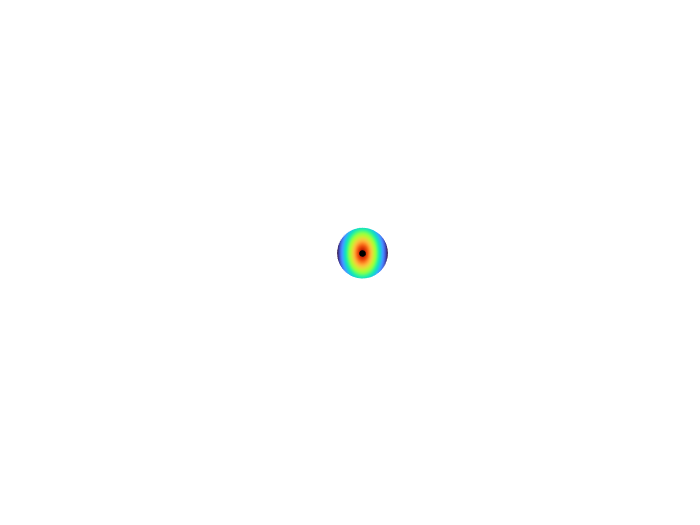

     2



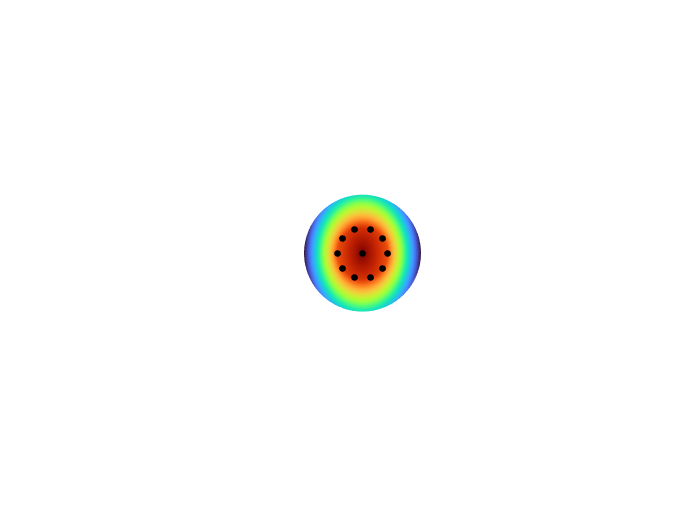

     3



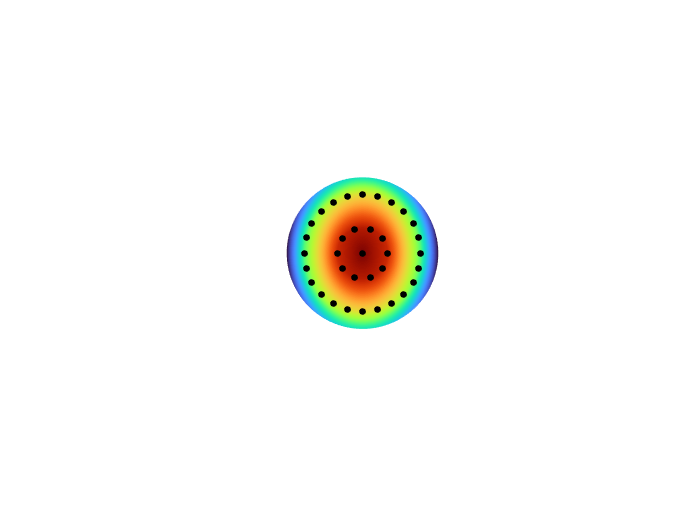

     4



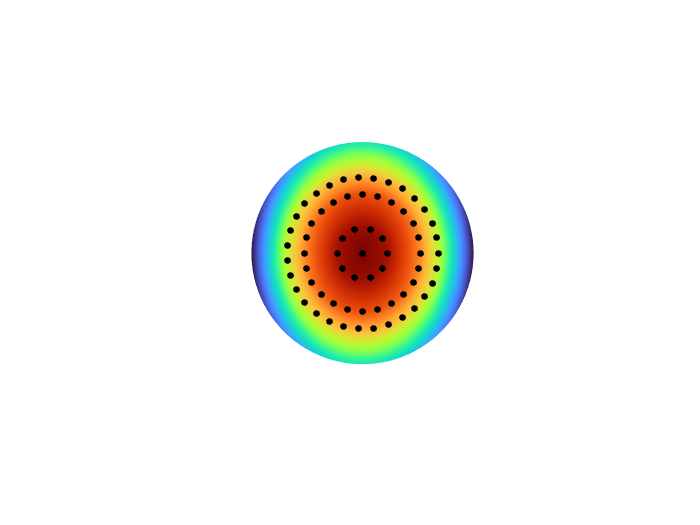

     5



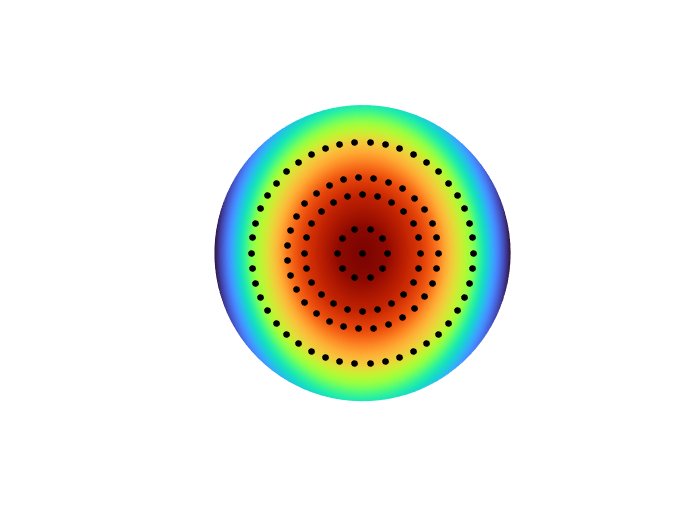

     6



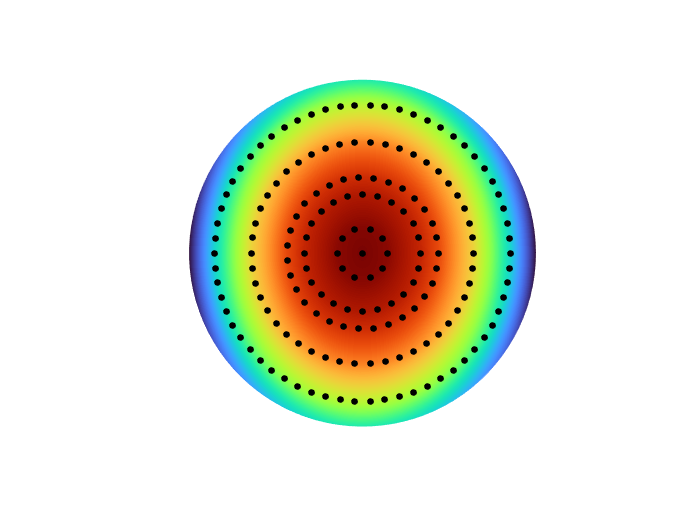

     7



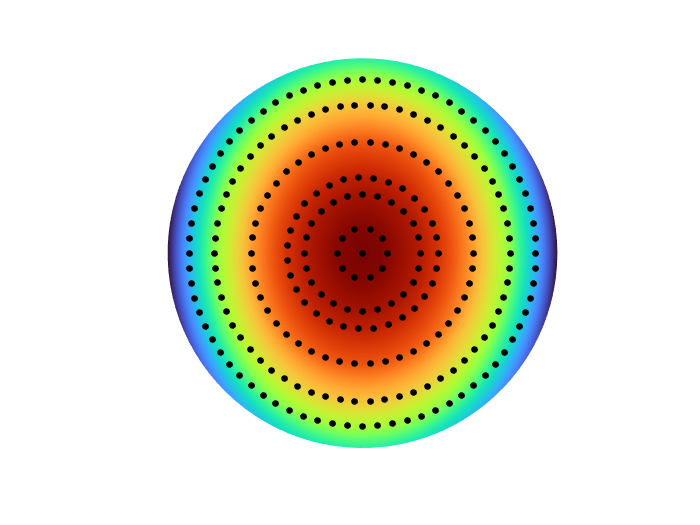

     8



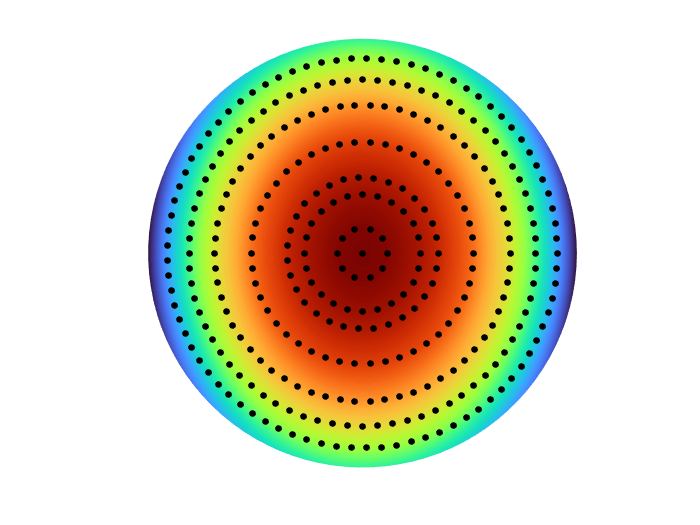

arcLength = 0.077;
r = [0,0.13,0.3,0.389,0.57,0.76,0.89,1];
spar = ceil(2*pi*r/arcLength);
xx = [];
yy = [];

syms x y;
R = 2;
A = 0.7;
B = 0.85;
surfSym = sqrt(R.^2 - x.^2/A^2 - y.^2/B^2);
surfFunc = matlabFunction(surfSym);
rr = [r(1:end),1.1];
ttheta = linspace(0,2*pi);
xxx = rr'*cos(ttheta);
yyy = rr'*sin(ttheta);
zzz = surfFunc(xxx,yyy);

for ii = 1:8
    disp(ii);
    theta = linspace(0,2*pi,spar(ii));
    xx = [xx,r(ii)*cos(theta)];
    yy = [yy,r(ii)*sin(theta)];
    figure;
    surf(xxx(1:ii + 1,:),yyy(1:ii + 1,:),zzz(1:ii + 1,:),'EdgeColor','none','FaceColor','interp'); hold on;
    colormap turbo;
    plot(xx,yy,'.','Color',[0,0,0],'MarkerSize',12);
    hold on;
    scatter(0,0,12,'MarkerFaceColor',[0,0,0],'MarkerEdgeColor',[0,0,0]);
    axis equal
    set(gca,'xtick',[],'xticklabel',[],'xLim',[-1.1,1.1], ...
        'ytick',[],'yticklabel',[],'yLim',[-1.1,1.1]);
    set(gca,'XColor','white','YColor','white');
    view([0 -90]);
end

## 自由曲面

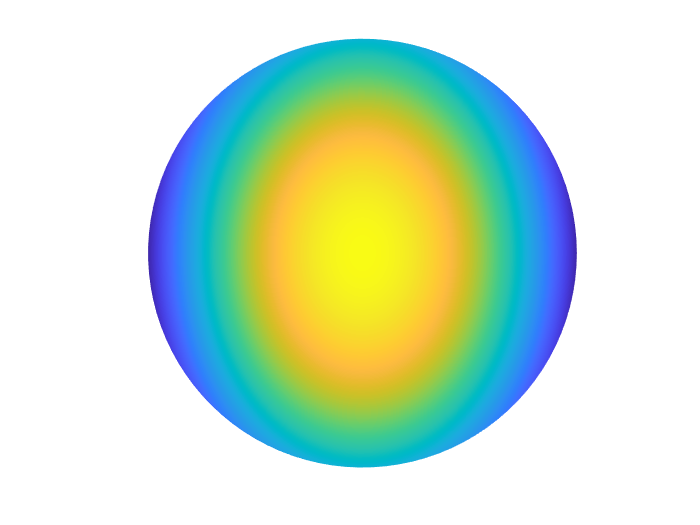

figure;
r = linspace(0,10,100);
theta = linspace(0,2*pi);
% xx = r'*cos(theta);
% yy = r'*sin(theta);
X = linspace(-10,10);
Y = linspace(-10,10);
[xx,yy] = meshgrid(X,Y);
syms x y;
R = 100;
A = 3;
B = 4;
C = 5;
surfSym = C*sqrt(R.^2 - x.^2/A^2 - y.^2/B^2);
surfFunc = matlabFunction(surfSym);
zz = surfFunc(xx,yy);
surf(xx,yy,zz,'EdgeColor','none','FaceColor','interp');
axis equal;
set(gca,'xtick',[],'xticklabel',[], ...
    'ytick',[],'yticklabel',[], ...
    'ztick',[],'zticklabel',[]);
set(gca,'XColor','white','YColor','white','ZColor','white');
view([0 90]);

## 贴图

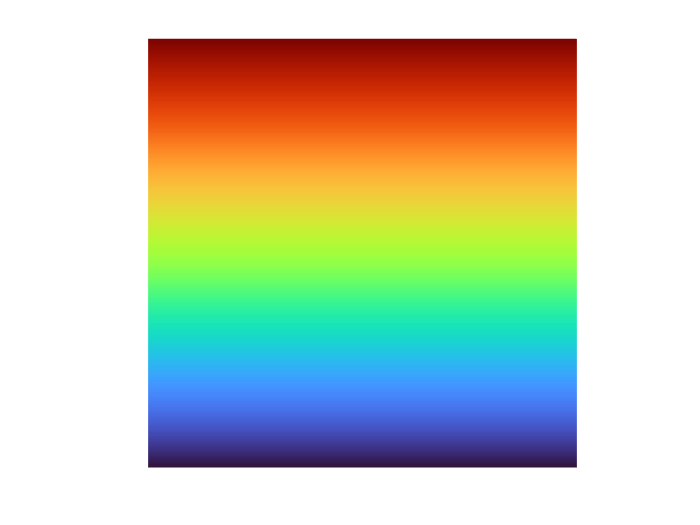

X = linspace(-10,10);
Y = linspace(-10,10);
[xx,yy] = meshgrid(X,Y);

zz = yy;
figure;
surf(xx,yy,zz,'EdgeColor','none','FaceColor','interp');
colormap turbo;
axis equal;
set(gca,'xtick',[],'xticklabel',[], ...
    'ytick',[],'yticklabel',[], ...
    'ztick',[],'zticklabel',[]);
set(gca,'XColor','white','YColor','white','ZColor','white');
view([0 90]);